# Lecture 3 notes

Welcome to part 3! Here are some of the things we looked at last time:

- Declaring different types of variables (e.g. numeric, characters, logical values) using the assignment operator `(=)`. MATLAB stores all variables as (multidimensional) arrays.

numeric = 5.78; % 1x1 numeric array
character = 'TextString'; % 1x10 character array
logical = false; % 1x1 logical array

- Indexing is very useful to extract and/or replace specific values of an array. Look at the code below and see if you can figure out what it does:

newMatrix = [1 5 3;4 -5 -2; 0 2 -9]
newMatrix([1,2],1) = [0;0]

- The colon operator `(:), which can be used to `create an evenly space vector (`1:3` gives `[1 2 3]`) can also be used for indexing into arrays: 

tinyMatrix = newMatrix(1:2,1:2) % Extract the first two columns and rows

- Relational operators, such as "larger than" or "equal to", and logical operators, such as "AND" or "OR", can be used to evaluate logical statements, such as whether a matrix contains values above a specific threshold or not:

between0and4 = tinyMatrix >= 0 & tinyMatrix < 5

The code above evaluates which elements in tinyMatrix are between 0 and 4.

- MATLAB contains a large number of built-in functions, such as `randi`, `mean`, and `std`, which take one or more inputs and produces one or more outputs:

nTrueValues = sum(between0and4) % sums the number of true values in each column
mean1to5 = mean([1 2 3 4 5]) % calculate mean of the vector 1:5

- Finally, recall that if you feel that you could use some more practice with MATLAB, the self-paced course [MATLAB onramp](https://se.mathworks.com/learn/tutorials/matlab-onramp.html) is recommended. There is also a more extensive follow-up course to onramp, called [MATLAB fundamentals](https://se.mathworks.com/learn/online-courses/matlab-fundamentals.html?s_tid=srchtitle_matlab%20fundamentals_1).

## Scripting in MATLAB

When we work with EEG data in the lab, we often want to do the same thing repeatedly, such as running a sequence of preprocessing steps on every subject. We could do this manually in the command window, running certain functions over and over again, but it can both take a very long time and is prone to errors. So instead, a better way to do it is to use *scripts*, which are used to automatically perform a series of commands, one after another, on the input you specify (such as EEG data). Using scripts also has the benefit of saving your commands between work sessions, so you do not need to remember everything for the next session. MATLAB plugins, such as EEGLAB and ERPLAB (or SPM for fMRI analysis), are essentially large collections of MATLAB scripts working together to do things automatically.

### The Script Editor

To get started, go to the **Home** tab in the MATLAB menu and click on **New Script**.

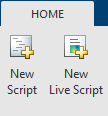

This opens up the script editor. We can start by saving our script by clicking **Save** > **Save As** in the **Editor **tab and name it something like `test`. Scripts are saved as `.m` files, while workspace variables are saved as `.mat` files (see below).

Let us start typing inside the script editor (use the enter key to go to a new line):

clear % clear Workspace
clc % clear Command Window
matrixA = randi(5,10,10);
matrixB = randi(7,10,10);
matrixC = matrixA .* matrixB;
sz = size(matrixC);

Then, click the green play button that says **Run**.

- I created three matrices above, how?

- What does the `size` function above do?

Now, run the same commands again, but this time remove the semicolons `(;)` at the end of each line. Notice the difference? When you click Run, MATLAB runs every line of the script, one at a time, from top to bottom, as if you were typing them into the Command Window.

We can use the function `save` to store the variables we produce with the script:

save('myVariables') % Save Workspace as myVariables.mat
save('matrixA.mat', 'matrixA') % Save matrixA as matrixA.mat

To load a saved variable into the Workspace, right-click it in the Current Folder and choose Load, or use the `load` function:

load('matrixA') % must be in current folder or you will need additional input arguments

Some useful information: MATLAB contains several [keyboard shortcuts](https://se.mathworks.com/help/matlab/matlab_env/keyboard-shortcuts.html). For example (on windows), you can run your script by pressing F5 instead of the run button, or run a part of your script by highlighting that part and pressing F9. You can also comment out one or more lines of your code using Ctrl + R (Ctrl + T to reverse). If you go to Home > Preferences > Keyboard > Shortcuts, you can view these keyboard shortcuts (and change them if you would like). 

Try using ctrl + R (⌘ + / on Mac?) to comment out your previous code, and then type in the following code in your script:

a = 1:10000000 % vector from 1 to 10000000

If you want to abort the process, use the Ctrl + C (⌘ + C on Mac) shortcut. Make sure that you click in the Command Window first. This shortcut is very useful to remember.

Now, add a semicolon `(;)` to the end (to suppress output) and run the line again. The variable ***a*** is now created immediately, illustrating that it takes a lot longer for MATLAB to print things into the Command Window than it takes doing the calculation. Remember that you can uncomment your previous code again with Ctrl + T (⌘ + T).

In the **Home > Preferences > Keyboard > Shortcuts** menu option, you can select whether to use the Windows Default or the Emacs Default (Mac and Linux) keyboard shortcuts. It is possible to use Windows Default on Mac or Linux, if one so desires.

Now, let us look at an example of code readability. Below, I use three different approaches to calculate the area of a 5x4 cm rectangle. Which part do you think is the most clear?

x = 5;
y = 4;
z = x*y;

- Try running one line above by highlighting it `x=5`, without the semicolon, right-clicking, and choosing **Evaluate Section in Command Window**.

height = 5;
width = 4;
area = height * width;

% The following code calculates the area of a 5x4 rectangle:
height = 5;   % Height of the rectangle (cm)
width  = 4;   % Width of the rectangle (cm)
area   = height * width;   % Compute the area of the rectangle (cm^2)

Hopefully, you will agree with me that the last block of code was the easiest to understand. Also, to make your code a bit more readable, it can be helpful to create sections in your scripts. Compare the code above with the one below:

x = 7;
y = 3;
z = x*y;
height = 5;
width = 4;
area = height * width;
height = 5;   % Height of the rectangle (cm)
width = 4;   % Width of the rectangle (cm)
area = height * width;   % Compute the area of the rectangle (cm^2)

Here, everything is cluttered, and it is harder to differentiate between the three different approaches. 

#### The Code Analyzer

MATLAB automatically analyzes the code in the Editor window, giving you various **warnings** and **error messages**. For example, write the following code in the script editor:

for i=1:4
    myVar(i)=i;
end

I will cover what a `for-loop` is later, so for now, let us focus on the red squiggly line under the variable myVar. If you hover over it, MATLAB is warning us that `myVar` will grow with each iteration, along with a suggestion to preallocate for speed. Here, we are being told to initialize variables to improve speed and prevent possible unwanted effects, which will be covered later. Receiving a warning means that the code will still run, but suboptimally. You can right-click on the underlined code and suppress the warning message, or you can simply ignore it.

If you receive an error message, however, MATLAB will crash on that line. Therefore, error messages need to be dealth with. The scroll bar on the right indicates warning and errors with horizontal bars colored orange and red, respectively. You can hover over the bar to see the message, and you can click on it to move the cursor to that line of code. You should consider it good practice to inspect all of the code analyzer's warnings, but whether you correct them should depend on if the warning is relevant for what you are trying to accomplish.

### The Live editor

Next, let us open up the live script editor as well by clicking **New Live Script** in the **Home** tab (or New in Editor tab). 

You can save it under **Save** > **Save as** (or ctrl+S) and name it `test`. Live scripts are saved as `.mlx` files.

Unlike in the regular script editor, the output is produced inside the document and not in the Command Window. Under the **View** tab, you can choose if you want your output on the right-hand side or below your commands.

Upon opening the live scripts, a block of code will first appear, and you can write your code there, just as in the Script Editor. You can also create sections of code by click Section Break, which will run independetly of each other (using Run Section instead of Run).

You can also click on **Text** and insert plain text, headers, bullet points, and so on. You can also go to the **Insert** tab to insert links and images.

You can use whichever editor you prefer (or both), but be aware that most of the files in MATLAB, EEGLAB, and ERPLAB are written in the regular Script Editor (`.m` files), so you should at least have a basic understanding of this editor. 

## Programming more general

This section contains a very brief introduction to programming more generally than we have previously covered. The hope is to give you a sense of what is going on "under the hood" when we write code, but also to introduce some basic programming concepts (*italicized* below) that you are likely to come across on your journey of learning how to code (no matter what language you end up using).

Programming is about solving problems using a computer. We, therefore, need to be able to tell the computer what to do. The computer, however, does not speak the same language as us humans. 

Inside a computer are billions of tiny switches (called transistors) that are either on or off. We say that one of these switches stores one *bit* of information (ON or OFF). So, how could we *represent complex information*, such as videos, websites, and MATLAB, by only turning on and off these switches?

First, we could say that ON is `1` and OFF is `0`. We could then represent the numbers that we are used to (base-10, or decimal system) with a *binary* *number* system of 1s and 0s (base-2). For example, the number 50 is represented as `110010` in binary.

Next, to represent things other than numbers, such as letters of the alphabet, we could assign a letter to a specific number, which we would all have to agree upon (e.g. A could be 1, B could be 2, and so on). This was done in the 60s, where people invented an encoding system called ASCII, containing 128 characters (such as upper and lowercase letters) matched to binary numbers. In ASCII, A is represented by 65 (`1000001`) and B is represented by 66 (`1000010`). ASCII is still used to day, for example when you save something to a .txt file, but it has also been extended into a system called [*Unicode*](https://en.wikipedia.org/wiki/Unicode)* Transformation Formats (*[*UTF*](https://en.wikipedia.org/wiki/UTF-8)*)*, containing over 1 million characters (or "*code points*").

Let us take a look at this with a code example (don't worry about remembering these specific functions):

hi = 'Hi!' % character variable

Below, I convert the characters "H", "i", and "!" to their Unicode numbers:

unicodeValues = double(hi)

I then convert these numbers into binary:

binaryRepresent = dec2bin(unicodeValues) % same as dec2bin(hi)

We can see that the string 'Hi!' consists of the numbers [72, 105, 33], which in turn are a bunch of binary numbers (in *groups of 8* *binary digits (bits)*, called a *byte*). This binary code is what the computer reads and understands. It is called *machine code, *while the human-readable code we write is called *source code*. MATLAB automatically *compiles* (translates) source code into machine code when we run our code. 

When we are programming, we are essentially writing a program explaining step-by-step what tasks the computer should perform. *Algorithms* are step by step instructions for solving problems. For example, if you have ever cooked dinner using a recipe, you were using an algorithm. However, computers need much more precise instructions to exectue algorithms and solve problems.

Let us look at a relatively simple algorithm written in so-called *pseudocode*, which is a plain text description of what you want the code to do, written with a similar structure to real code. Pseudocode can be a helpful way to get an initial overview of what you want your code to do before you start working with all the specific commands, and I strongly recommend using it. Here is the pseudocode:

- What would happen if we entered the value 19 above?

The pseudocode above takes an input value and responds differently based on what that value is. This is known as *conditional control* (also decision branching), and is one of three types of* control flow:*

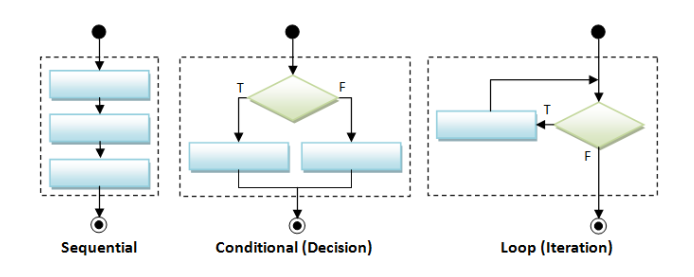

The image shows different possibilities to control the execution of commands in Matlab and is taken from https://www3.ntu.edu.sg/home/ehchua/programming/java/images/Flowchart_FlowControl.png

As mentioned earlier, MATLAB executes each statement in a script sequentially by default (left). However, you may want some lines of code to only run if some condition holds, such as if the data from a subject does not contain too much noise. You can accomplish this by specifying one or several *conditional statements* (middle), which are statements that execute some specific lines of code only if some specific condition is true. Finally, *loops *(right) execute the same lines of code over and over until some end condition is reached (such as until the loop has been executed 5 times, or until the end result reaches some specific threshold or similar).

## Conditional control: The if statement

The `if` statement (also called if-elseif-else or IF-THEN statements) in MATLAB has the following structure:

Let us get a better feel with some examples:

yourNumber = 25;

if yourNumber == 20 % this is False, so it moves on to the else statement
    disp('Your number is 20.')
else % This is True, so it exectues the command below
    disp('Your number is not 20.')
end

Above, we declared a variable called ***yourNumber***. We then used an `if` statement to evaluate if yourNumber` == 20` (true or false). The `else` statement tells MATLAB what to do if the `if` statement is false. We must end our conditional statements with an `end` statement, to tell MATLAB that it should stop looking for condition-specific code, and just process the subsequent code like normal (sequentially). 

- Make sure that you actually type these statements into your script, to get a feel for how MATLAB uses *indentation* automatically. This makes the code easier to follow, especially when you start creating more complex processes. You could also consider how you would make the code above easier to read.

In the code above, we had one condition (either yourNumber is 20 or not). Now, let us return to the pseudocode we looked at earlier, but this time with actual MATLAB code. Here, we have more than one condition, i.e. ***yourNumber*** is either "equal to", "larger than", or "less than" 20. Let us also introduce some chance and make ***yourNumbe***r a random integer.

yourNumber = randi(40) % Random integer between 1 and 40.

if yourNumber == 20
    disp('Your number is 20');
elseif yourNumber > 20
    disp('Your number is greater than 20');
else
    disp('Your number is less than 20');
end
disp('Finished!')

- Why was my last conditional statement just `else`, not "`elseif yourNumber < 20`"?

Here is a final example, illustrating how you can combine numbers with text by using the built-in function `num2str.`

yourNumber = randi(40); % Random integer between 1 and 40.

if yourNumber > 20
    disp(['Your number is ' num2str(yourNumber) ', which is greater than 20']);
elseif yourNumber < 20
    disp(['Your number is ' num2str(yourNumber) ', which is less than 20']);
else
    disp(['Your number is ' num2str(yourNumber) ', which is equal to 20']);
end

Just as before, we are evaluating if the random variable ***yourNumber*** is larger, smaller, or equal to 20. Here, however, the message we display is a bit more complex. Consider the code below:

a  = [1 2]
b  = [3 4]
ab = [a b] % combine, or concatenate, the two vectors into one. 

Above, we combine two vectors into one, by placing b after a inside a new vector. We touched upon this in the previous lecture. We can create character arrays in a similar manner that we can create vectors and matrices, we just need to be careful with putting our text inside the `''` characters:

hi = 'hi!' % character vector
hiThere = [hi 'there'] % combine with another character vector 'there'
hiThere2 = [hi ' there'] % looks better with a space before there
hiThere3 = [hi; 'ho!'] % we can also make a column vector of characters

Creating variables first can make it a bit easier:

a = 'Hello my number is '
b = num2str(25)
c = ', which is a perfectly fine number.'
myCharArray = [a b c]

- I recommend playing around a bit with creating different sentences this way to get a better feel for what works and what does not.

**Summary**

- When we work with EEG data in the lab, we often want to do the same thing repeatedly. We use scripts to automatically perform a series of MATLAB commands, one after another.

- Programming is about solving problems using a computer. To do so, we write step-by-step instructions, telling the computer exactly what to do. An algorithm is the set of steps taken to solve a given problem.

- There are three different types of control flow, the order in which our commands are executed. Sequential, i.e. in order from start to finish, is the default in MATLAB. Conditional statements are statements that execute some specific command only if some specific condition is true. Loops repeat a set of commands until some condition is met. We will cover loops next lecture.

- If statements allow us to choose between different "decisions" when we code, such as whether or not to drop a participant from our analysis due to the data containing too much noise.